# Assignment 2

## Consider the following two sets of observed 1D data (feature values) coming from objects of two different classes (read the data from the file lab3 1.mat): S1, S2; and the following test set of data points that need to be classified: T.

1. Plot the elements of the two sets S1 and S2 on the x-axis of a Fig. 1: the elements of S1 as blue circles (bo) and the elements of the set S2 as red circles (ro). Plot in the same Fig. 1 the points of the test set T as black squares (ks).

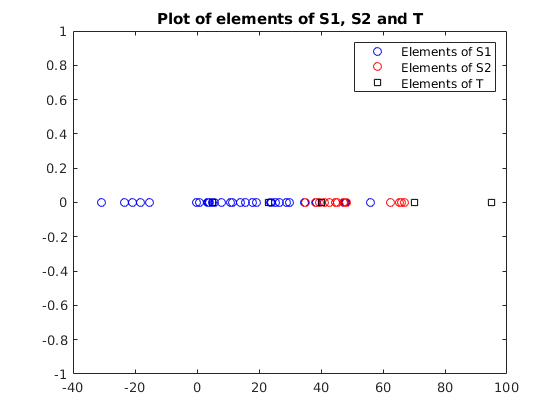

ps1 = plot(S1, zeros(1,numel(S1)), 'bo');
hold on
ps2 = plot(S2, zeros(1,numel(S2)), 'ro');
pt = plot(T, zeros(1,numel(T)), 'ks');
title('Plot of elements of S1, S2 and T')
legend([ps1 ps2 pt],'Elements of S1', 'Elements of S2', 'Elements of T')

2. Let’s assume S1 and S2 are drawn from normal distributions. Compute the parameters (mean and standard deviation) of the two distributions, using maximum estimation. Create a Fig.2 in which you plot the two Gaussian functions, one in blue the other in red, together with the points of the two training data sets S1 and S2. The two functions are the class conditional probability densities p(x|ω1) and p(x|ω2) that the two classes produce a value x of the considered feature. Comment on the use of the functions, in comparison to using the rugged data.

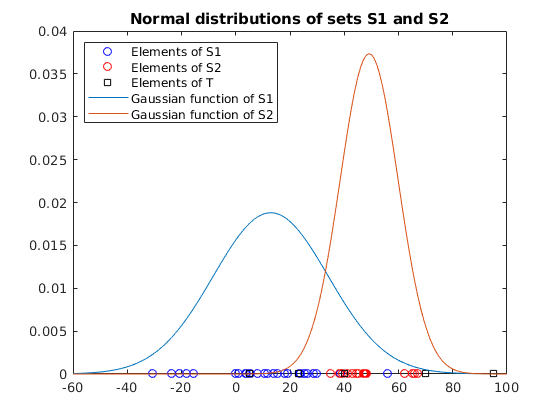

% Get the limits to establish a range
xlimits = xlim;
xrange = xlimits(1)-20:xlimits(2);
% Compute the mean and standard deviation
mean_S1 = mean(S1);
std_S1 = std(S1);
% Plot the normal distribution with the parameters previously computed
norm_S1 = normpdf(xrange, mean_S1, std_S1);
pns1 = plot(xrange, norm_S1);
% Do the same for set S2
mean_S2 = mean(S2);
std_S2 = std(S2);
norm_S2 = normpdf(xrange, mean_S2, std_S2);
pns2 = plot(xrange, norm_S2);

title('Normal distributions of sets S1 and S2')
legend([ps1 ps2 pt pns1 pns2], 'Elements of S1', 'Elements of S2', 'Elements of T', 'Gaussian function of S1', 'Gaussian function of S2', 'Location', 'northwest')

hold off

We can use the function to calculate the probability of any point whether we have it in our data set or not.

3. Estimate the prior probabilities P(ω1) and P(ω2).

el_S1 = numel(S1);
el_S2 = numel(S2);
p_w1 = el_S1./(el_S1 + el_S2);
p_w2 = el_S2./(el_S1 + el_S2);

fprintf("The estimated probability for w1 is: %.4f", p_w1)

The estimated probability for w1 is: 0.6667

fprintf("The estimated probability for w2 is: %.4f", p_w2)

The estimated probability for w2 is: 0.3333

4. Create a Fig. 3 in which you plot the two products P(ω1)p(x|ω1) and P(ω2)p(x|ω2), together with the points of the two training data sets S1 and S2 and the test set T.

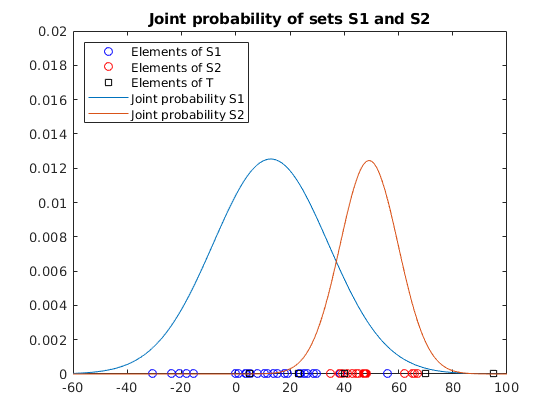

% First plot the values of S1, S2, and T on the x-axis
ps1 = plot(S1, zeros(1,numel(S1)), 'bo');
hold on
ps2 = plot(S2, zeros(1,numel(S2)), 'ro');
pt = plot(T, zeros(1,numel(T)), 'ks');
% Then plot the normal distributions times the prior probabilities
p1 = p_w1.*norm_S1;
p2 = p_w2.*norm_S2;
pjs1 = plot(xrange, p1);
pjs2 = plot(xrange, p2);
title('Joint probability of sets S1 and S2')
legend([ps1 ps2 pt pjs1 pjs2], 'Elements of S1', 'Elements of S2', 'Elements of T', 'Joint probability S1', 'Joint probability S2', 'Location', 'northwest')
ylim([0 0.02])
hold off

5. Substitute the values of the prior probabilities and the class conditional probability densities determined above in the equation P(ω1)p(x|ω1) = P(ω2)p(x|ω2) and solve the resulting equation for x in order to determine the value(s) of the decision criterion that we should use for classiﬁcation.

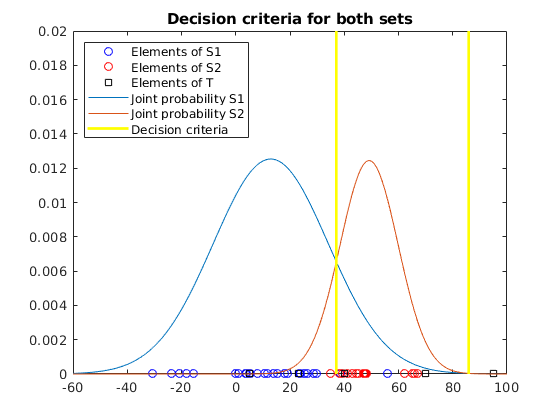

% Solve the equation P(ω1)p(x|ω1) = P(ω2)p(x|ω2)
sympref('FloatingPointOutput', true);
syms x
eqn = p_w1*(1/(std_S1*sqrt(2*pi)))*exp(-(x-mean_S1)^2/(2*std_S1^2)) == p_w2*(1/(std_S2*sqrt(2*pi)))*exp(-(x-mean_S2)^2/(2*std_S2^2));
xSol = solve(eqn, x);
% Obtain both solutions
x1 = xSol(1);
x2 = xSol(2);
% Plot them in the graph as a line
pdc1 = line([x1, x1], ylim, 'LineWidth', 2, 'Color', 'y');
pdc2 = line([x2, x2], ylim, 'LineWidth', 2, 'Color', 'y');
title('Decision criteria for both sets')
legend([ps1 ps2 pt pjs1 pjs2 pdc1], 'Elements of S1', 'Elements of S2', 'Elements of T', 'Joint probability S1', 'Joint probability S2', 'Decision criteria', 'Location', 'northwest')
ylim([0 0.02])


fprintf('First decision criterion: %.4f', x1)

First decision criterion: 37.0697

fprintf('Second decision criterion: %.4f', x2)

Second decision criterion: 85.8863

6. Using the thus obtained value(s) of the decision criterion, determine the classes of the points in the test set [5 23 40 70 95]. Create a Fig. 4 which copies Fig. 3 and adds to it a specification of which domain on the x-axis belongs to class 1 (blue) and which complementary domain corresponds to class 2 (red).

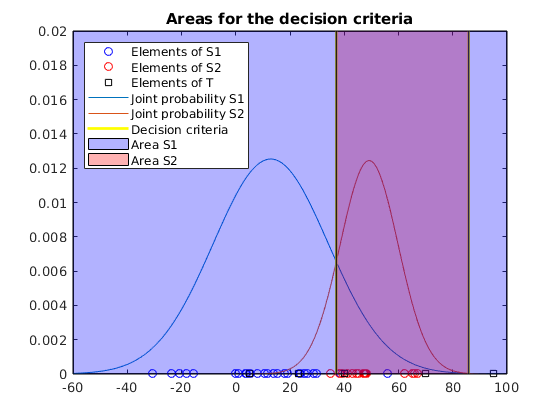

% Paint the areas separated by the decision criteria
ylimits = ylim;
hold on
areaS1 = area([xrange(1) x1], [ylimits(2) ylimits(2)], 'FaceColor', 'b', 'FaceAlpha', 0.3);
areaS2 = area([x1 x2], [ylimits(2) ylimits(2)], 'FaceColor', 'r', 'FaceAlpha', 0.3);
area([x1 xrange(end)], [ylimits(2) ylimits(2)], 'FaceColor', 'b', 'FaceAlpha', 0.3);
title('Areas for the decision criteria')
legend([ps1 ps2 pt pjs1 pjs2 pdc1 areaS1 areaS2], 'Elements of S1', 'Elements of S2', 'Elements of T', 'Joint probability S1', 'Joint probability S2', 'Decision criteria', 'Area S1', 'Area S2', 'Location', 'northwest')
hold off


% Classify the set T into both classes
set_S1 = T(T < x1 | x2 < T);
set_S2 = T(x1 < T & T < x2);

fprintf(strcat(['The points that belong to S1 are:', ' ', num2str(set_S1)]))

The points that belong to S1 are: 5  23  95

fprintf(strcat(['The points that belong to S2 are:', ' ', num2str(set_S2)]))

The points that belong to S2 are: 40  70

7. Evaluate the misclassification rate of the created classifier for each of the two classes. (For this, you can for instance use the error function erf, familiar from the iris recognition assignment in the first week.)

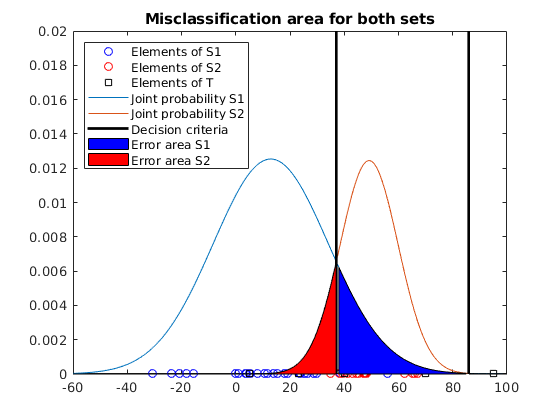

% Plot all the graphs previously computed
ps1 = plot(S1, zeros(1,numel(S1)), 'bo');
hold on
ps2 = plot(S2, zeros(1,numel(S2)), 'ro');
pt = plot(T, zeros(1,numel(T)), 'ks');
ylim([0 0.02])
p1 = p_w1.*norm_S1;
p2 = p_w2.*norm_S2;
pjs1 = plot(xrange, p1);
pjs2 = plot(xrange, p2);
pdc1 = line([x1, x1], ylim, 'LineWidth', 2, 'Color', 'k');
pdc2 = line([x2, x2], ylim, 'LineWidth', 2, 'Color', 'k');
title('Misclassification area for both sets')
% Paint the areas we want to calculate. To do this, we use the x-axis range
% used to plot the graphs and take all the values that need to be painted,
% then use the joint probability function to determine its Y value and
% paint the area
areaS2 = area(xrange(xrange < x1), p2(xrange(xrange < x1) + 61), 'FaceColor', 'r');
areaS1 = area(xrange(x1 < xrange & xrange < x2), p1(xrange(x1 < xrange & xrange < x2) + 61), 'FaceColor', 'b');
area(xrange(x2 < xrange), p2(xrange(x2 < xrange) + 61), 'FaceColor', 'r');
legend([ps1 ps2 pt pjs1 pjs2 pdc1 areaS1 areaS2], 'Elements of S1', 'Elements of S2', 'Elements of T', 'Joint probability S1', 'Joint probability S2', 'Decision criteria', 'Error area S1', 'Error area S2', 'Location', 'northwest')
hold off

% Finally, calculate the areas using the CDF of the normal distributions
% times the prior probabilities
errArea_S1 = normcdf(x2, mean_S1, std_S1) - normcdf(x1, mean_S1, std_S1);
errArea_S1 = errArea_S1 * p_w1;
errArea_S2 = normcdf(x1, mean_S2, std_S2) + 1 - normcdf(x2, mean_S2, std_S2);
errArea_S2 = errArea_S2 * p_w2;

fprintf('S1 error is: %.4f', errArea_S1)

S1 error is: 0.0847

fprintf('S2 error is: %.4f', errArea_S2)

S2 error is: 0.0429